load gTruth.mat

if ~isfolder(fullfile("TrainingDataCustomMultiDetect"))
    mkdir TrainingDataCustomMultiDetect
end

trainingData1 = objectDetectorTrainingData(gTruth, 'SamplingFactor',1,... 
    'WriteLocation', 'TrainingDataCustomMultiDetect');

Write images extracted for training to folder: 
    TrainingDataCustomMultiDetect

Writing 98 images extracted from Output.mp4...Completed.


trainingData = [trainingData1];

trainingData(1:4,:)

ans = 4×2 table
                      imageFilename                          cone    
    _________________________________________________    ____________

    {'TrainingDataCustomMultiDetect\Output1_001.png'}    {4×4 double}
    {'TrainingDataCustomMultiDetect\Output1_008.png'}    {4×4 double}
    {'TrainingDataCustomMultiDetect\Output1_016.png'}    {4×4 double}
    {'TrainingDataCustomMultiDetect\Output1_023.png'}    {4×4 double}



rng(0);

shuffledIndices = randperm(height(trainingData));
idx = floor(0.8 * length(shuffledIndices));
trainingIdx = 1:idx;
testIdx = trainingIdx(end)+1: length(shuffledIndices);

trainingDataset = trainingData(shuffledIndices(trainingIdx),:);
testDataSet = trainingData(shuffledIndices(testIdx),:);

inputSize = [720 1280 3];
inputLayer = imageInputLayer(inputSize, 'Name','input','Normalization','none');

filterSize = [3 3];

middlelayers = [
    convolution2dLayer(filterSize, 16, 'Padding', 1, 'Name', 'conv_1',...
    'WeightsInitializer', 'narrow-normal')
    batchNormalizationLayer('Name', 'BN1')
    reluLayer('Name', 'relu_1')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'maxpool1')
    convolution2dLayer(filterSize, 32, 'Padding', 1, 'Name', 'conv_2',...
    'WeightsInitializer', 'narrow-normal')
    batchNormalizationLayer('Name', 'BN2')
    reluLayer('Name', 'relu_2')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'maxpool2')
    convolution2dLayer(filterSize, 64, 'Padding', 1, 'Name', 'conv_3',...
    'WeightsInitializer', 'narrow-normal')
    batchNormalizationLayer('Name', 'BN3')
    reluLayer('Name','relu_3')
    maxPooling2dLayer(2, 'Stride', 2, 'Name', 'maxpool3')
    convolution2dLayer(filterSize, 128, 'Padding', 1, 'Name', 'conv_4',...
    'WeightsInitializer', 'narrow-normal')
    batchNormalizationLayer('Name', 'BN4')
    reluLayer('Name', 'relu_4')
    ];
lgraph = layerGraph([inputLayer; middlelayers]);
numClasses = size(trainingData,2)-1;

trainingData11 = boxLabelDatastore(trainingData(:,2:end));

numAnchors = 10;
[anchorBoxes,meaIoU] = estimateAnchorBoxes(trainingData11,numAnchors);

lgraph = yolov2Layers(inputSize,numClasses,anchorBoxes,lgraph,'relu_4');


*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* cone

Checking training data...done.
Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:20 |        51.22 |       2623.2 |          0.0010 |
|       9 |          50 |       00:08:17 |         3.67 |         13.4 |          0.0010 |
|      17 |         100 |       00:16:06 |         3.66 |         13.4 |          0.0010 |
|      25 |         150 |       00:24:17 |         3.30 |         10.9 |          0.0010 |
|      34 |         200 |       00:32:12 |         3.40 |        

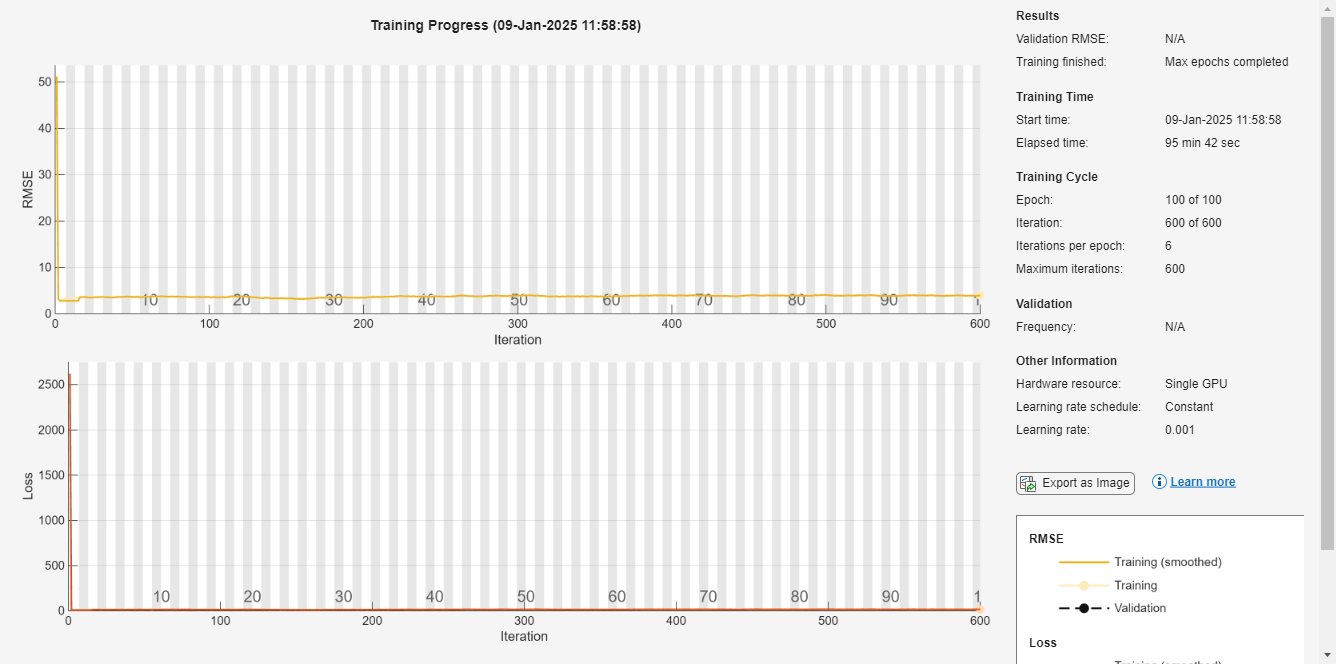

Detector training complete.
*************************************************************************




doTraining = true;

if doTraining
    rng(0);

    options = trainingOptions('sgdm', ...
        'InitialLearnRate', 0.001, ...
        'Verbose', true, ...
        'MiniBatchSize', 16,...
        'MaxEpochs',100, ...
        'Shuffle','every-epoch', ...
        'VerboseFrequency', 50, ...
        'ExecutionEnvironment', 'auto',...
        'Plots',"training-progress");
    [yolov2ObjectDetector, info] = trainYOLOv2ObjectDetector(trainingData,lgraph,options);
    class=yolov2ObjectDetector;
    save('yolov2ConeDetector.mat','class')
else
    load('yolov2ConeDetector.mat');
end